Pn = 0.75*10^3; %номинальная мощность
nn = 930; %номинальная частота вращения (об/мин)
kpd = 70 /100; %коэффициент полезного действия
cosfi = 0.68; %коэффициент мощности
Un = 380/sqrt(3); %фазное напряжение питания
In = 2.4; %линейный или фазный ток 
Mn = 7.7; %номинальный момент нагрузки
ks = 2; %кратность пускового момента ks =Ms/Mn
ki = 4.5; %кратность пускового тока ki =Is/In
lyambda = 2.3; %кратность максимального момента λ=Mm/Mn

m = 3; %число фаз
f = 50; %частота сети
zp = 3; %число пар полюсов


n1 = 60*f/zp %частота вращения магнитного поля статора(скорость циклического изменения магнитного потока статора, называется синхронной скоростью двигателя)

n1 = 1000

sn = (n1-nn)/n1 %величина номинального скольжения

sn = 0.0700


N = 1000; %синхронная частота вращения (об/мин)
J = 0.0033; %
mass = 14; %
service_factor = 1.15; %

% Параметры схемы замещения
w1 = 2*pi*f %скорость вращения поля

w1 = 314.1593

2*pi*f/zp

ans = 104.7198


%------
Rs = (Un*In*cosfi-Mn*w1/m/zp)/In^2

Rs = 15.4981

Rr0 = m*zp*Un^2*sn/w1/Mn

Rr0 = 12.5356

%------

mu_m = @(r2_) mu_m_calc(r2_,Rs,sn,lyambda,In,cosfi,Un,m,zp,w1,Mn);
Rr = fzero(mu_m,Rr0)

Rr = 10.0995


a = Rs/Rr

a = 1.5345

A = 1-2*a*sn*(lyambda-1)

A = 0.7207

s_m = sn*(lyambda+sqrt(lyambda^2-A))/A

s_m = 0.4310

x_ks = sqrt((Rr/s_m)^2-Rs^2)

x_ks = 17.5752

b = x_ks/((Rs+Rr/sn)^2+x_ks^2)

b = 6.8022e-04

x_m = 1/((In*sqrt(1-cosfi^2))/Un-b)

x_m = 136.2290

x_s1 = x_ks/2;
x_s2 = x_ks/2;
I2_ = Un/sqrt((Rs+Rr/s_m)^2+(x_ks+x_m)^2)

I2_ = 1.3828

mu_m = m*zp*I2_^2*Rr/(w1*s_m*Mn)

mu_m = 0.1667


%------
h0 = 3;
mu_s = @(h) mu_s_calc(h,m,zp,Un,Rr,w1,Mn,Rs,x_s1,x_s2,ks);
h = fzero(mu_s,h0)

h = 1.1148


k_r = h*(sinh(2*h)+sin(2*h))/(cosh(2*h)-cos(2*h))

k_r = 1.1297

k_x = 3/2/h*(sinh(2*h)-sin(2*h))/(cosh(2*h)-cos(2*h))

k_x = 0.9631

mu_s = m*zp*Un^2*Rr*k_r/(w1*Mn*((Rs+Rr*k_r)^2+(x_s1+x_s2*k_x)^2))

mu_s = 2

% Электрическая частота
w0_ = 2*pi*f;
w_ = 0.1*w0_:0.1*w0_:w0_;
% Механическая частота
w_mech0 = 2*pi*f/zp;
w_mech = 0.1*w_mech0:0.1*w_mech0:w_mech0;
% Индуктивность обмоток
Ls = (x_s1+x_m) / w0_;
Lr = (x_s2+x_m) / w0_;
Lm = x_m / w0_;
% изменяющиеся индуктивные сопротивления рассеяния 
x_s = Ls * w_;
x_r = Lr * w_;
x_m = Lm * w_;

K_u = Lr/(Ls*Lr - Lm^2);
K_i = (Rs*Lr^2 + Lm^2*Rr)/(Ls*Lr^2 - Lm^2*Lr);
K_1 = Lm*Rr/(Ls*Lr^2 - Lm^2*Lr^2);
K_2 = Lm/(Ls*Lr - Lm^2);
K_3 = Lm*Rr/Lr;
K_4 = Rr/Lr;

% свое
u = 220*sqrt(2);
Ml = 8.86/1.5/3;
M_nagr = 18.86/1.5/3;
U_dc = 700;
slope = 1;

Первое задание

W = out.simout.signals.values(:,1);

Dot indexing is not supported
for variables of this type.

M = out.simout.signals.values(:,2);
i = out.simout.signals.values(:,3);
W_sim = out.simout.signals.values(:,4);
% W_sim = out.sim.Data(:,1);
% i_sim = out.sim.Data(:,2);
i_sim = out.simout.signals.values(:,5);
M_sim = out.simout.signals.values(:,6);
t = out.simout.time;


figure()
plot(t, M, 'LineWidth',2);
hold on
plot(t, M_sim, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('M, Н\cdotм');
legend('Simulink', 'Simscape');
figure()
% plot(M_mech_sim,w_mech_sim, 'LineWidth',2);
plot(t, W, 'LineWidth',2);
hold on
% plot(out.sim.Time, W_sim, 'LineWidth',2);
plot(t, W_sim, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('n, rad/sec');
legend('Simulink', 'Simscape');
% xlim([0 1]); ylim([0 140])

figure()
% plot(M_mech_sim,w_mech_sim, 'LineWidth',2);
plot(t, i, 'LineWidth',2);
hold on
% plot(out.sim.Time, i_sim, 'LineWidth',2);
plot(t, i_sim, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('I, A');
legend('Simulink', 'Simscape')
% xlim([0 1])

Второе задание

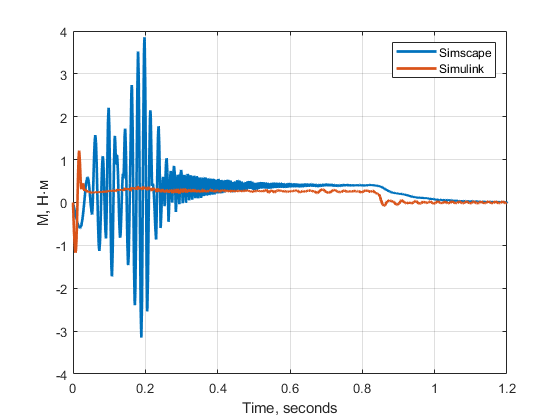

figure()
plot(out.M_sim_time.Time, out.simscape(:,1), 'LineWidth',2);
hold on
plot(out.M.Time, out.M.Data, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('M, Н\cdotм');
legend('Simscape', 'Simulink');
xlim([0 1.2])

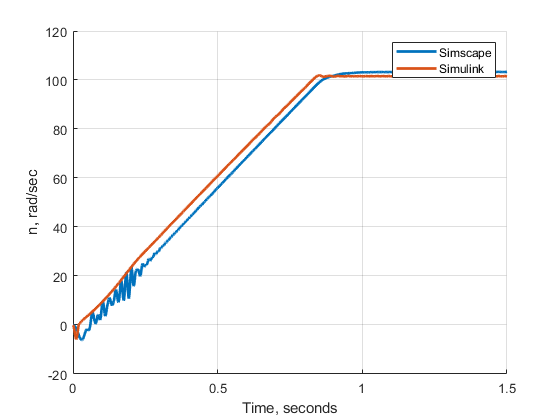


figure()
hold on
plot(out.w_sim_time.Time, out.simscape(:,2), 'LineWidth',2);
plot(out.w.Time, out.w.Data, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('n, rad/sec');
legend('Simscape','Simulink');
xlim([0 1.5])

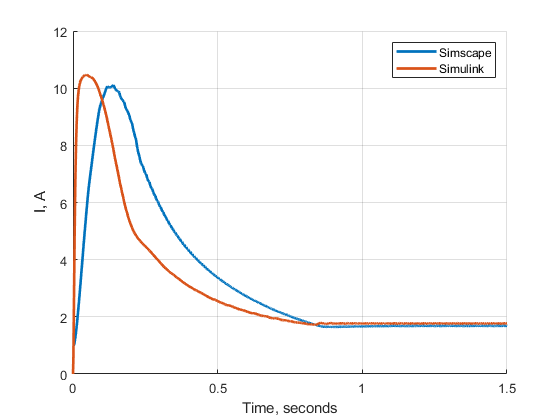


figure()
hold on
plot(out.I_sim_time.Time, out.simscape(:,3)+1.95, 'LineWidth',2);
plot(out.I_s.Time, out.I_s.Data, 'LineWidth',2);
hold off
grid on
xlabel('Time, seconds');
ylabel('I, A');
legend('Simscape','Simulink')
xlim([0 1.5])